load spectra
who


Your variables are:

B            B5           CIED50       G3           K1           M2           R4           X1           Y            Z            a            map          
B1           B6           CIED65       G4           K2           R            R5           X2           Y1           Z1           ans          plank90K     
B2           C            G            G5           L            R1           R6           X3           Y2           Z2           b            wavelength   
B3           C1           G1           G6           M            R2           Tungsten60W  X4           Y3           Z3           chips20      xyz          
B4           C2           G2           K            M1           R3           X            XYZ          Y4           Z4           f11          



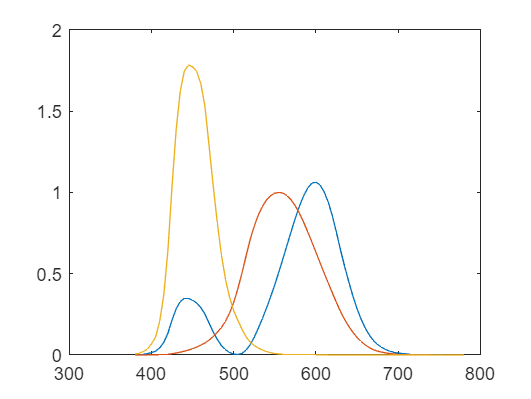


plot(wavelength, xyz)

figure
[X,Y,Z] = spectra2xyz(1, CIED65);


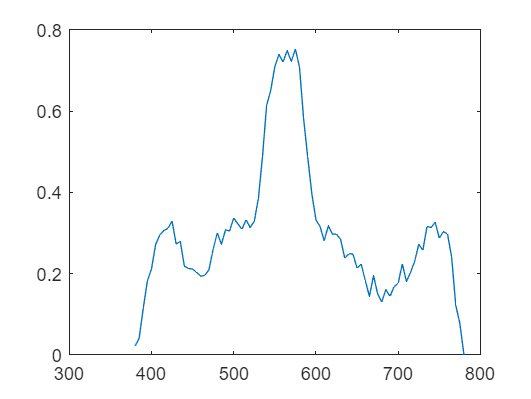

% 1.4 %
plot(wavelength, R1)

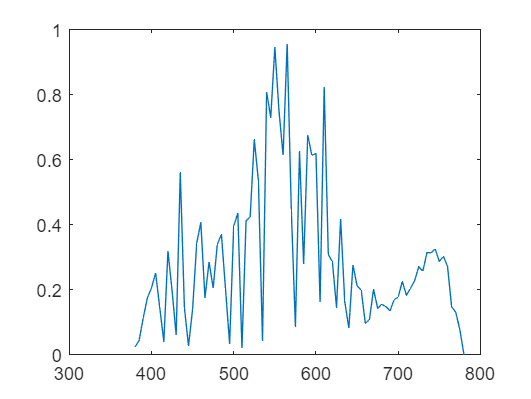


plot(wavelength, R2)


[X1,Y1,Z1] = spectra2xyz(R1, CIED65);
[X2,Y2,Z2] = spectra2xyz(R2, CIED65);

% 1.3 %

[X3,Y3,Z3] = spectra2xyz(R1, f11);
[X4,Y4,Z4] = spectra2xyz(R2, f11);

% 1.5 %
help myxyz2rgb

  [r,g,b] = myxyz2rgb(x,y,z)
 
 This function converts the CIEXYZ values to RGB assuming a monitor with a
  white point close to CIED65.
  x, y, z are the vectors containg the X, Y and Z values
  r, g, b are the vetors containg the R, G and B values



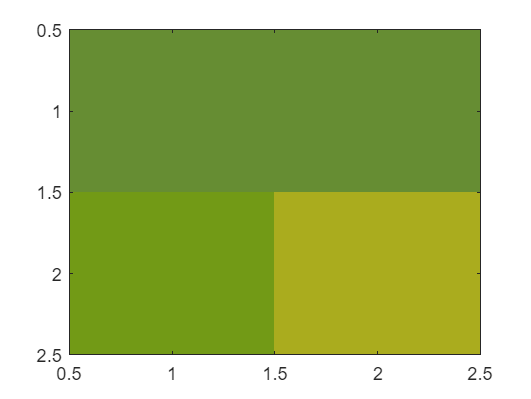


[R1, G1, B1] = myxyz2rgb(X1, Y1, Z1);
[R2, G2, B2] = myxyz2rgb(X2, Y2, Z2);
[R3, G3, B3] = myxyz2rgb(X3, Y3, Z3);
[R4, G4, B4] = myxyz2rgb(X4, Y4, Z4);

map = [R1 G1 B1; R2 G2 B2; R3 G3 B3; R4 G4 B4];
map=min(1,max(0,map));
image([1 2; 3 4])
colormap(map)

% 2.2 

disp("none")

none


[R1, G1, B1] = myxyz2rgb(80.43, 84, 96.5);

disp("cyan")

cyan


[R2, G2, B2] = myxyz2rgb(25.84, 42.52, 80.88);

disp("magenta")

magenta


[R3, G3, B3] = myxyz2rgb(37.36, 18.44 , 27.52);

disp("c + m")

c + m


[R4, G4, B4] = myxyz2rgb(7.40, 5.74, 40.36);

disp("dot on dot")

dot on dot


[R5, G5, B5] = myxyz2rgb(43.915, 44.87, 68.43);

disp("dot off dot")

dot off dot


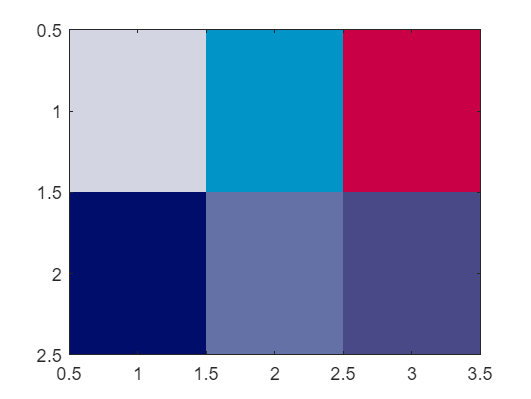

[R6, G6, B6] = myxyz2rgb(31.6, 30.48, 54.2);


map = [R1 G1 B1; R2 G2 B2; R3 G3 B3; 
       R4 G4 B4; R5 G5 B5; R6 G6 B6];
map=min(1,max(0,map));
image([1 2 3; 4 5 6])
colormap(map)

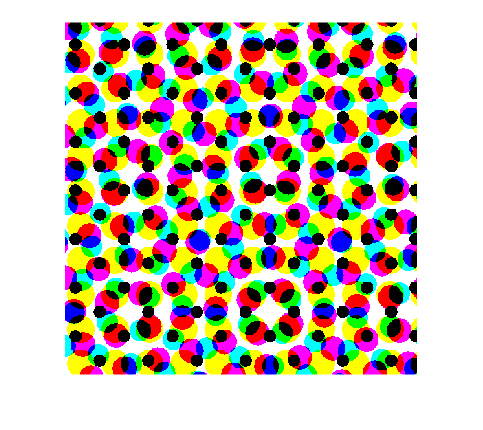

%3 
[C, M, Y, K]=tiffread("halftone.tif");
[R, G, B]=cmyk2rgb(C, M, Y, K);
imshowrgb(R, G, B)

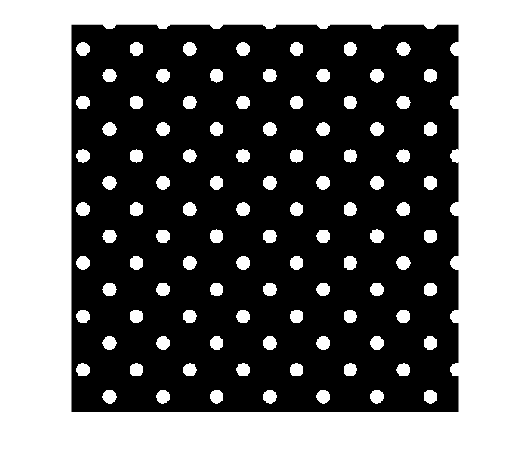

imshow(K)

% 3.1
C1=C(129:384,129:384);
M1=M(129:384,129:384);
Y1=Y(129:384,129:384);
K1=K(129:384,129:384);

help Demichel_test

 
  out=Demichel_test(C,M,Y,K)
  This function calculates the fractional coverages using Demichel's
  equations.
  C, M, Y and K are the matrices of the same size, representing the Cyan,
  Magenta, Yellow and Black channels.
 
  out is a 16 x 1 matrix consisting of the fractional coverages for, No ink,
  Only C, Only M, Only Y, Only K, (C & M), (C & Y), (C & K), (M & Y), (M &
  K), (Y & K), (C & M & Y), (C & M & K), (C & Y & K), (M & Y & K), (C & M &
  Y & K).




Demichel_test(C1,M1,Y1,K1);

C2=C(139:394,139:394);
M2=M(139:394,139:394);
Y2=Y(139:394,139:394);
K2=K(139:394,139:394);

Demichel_test(C2,M2,Y2,K2)

ans =     0.1636
    0.0818
    0.1349
    0.2072
    0.0183
    0.0624
    0.0827
    0.0101
    0.1132
    0.0198


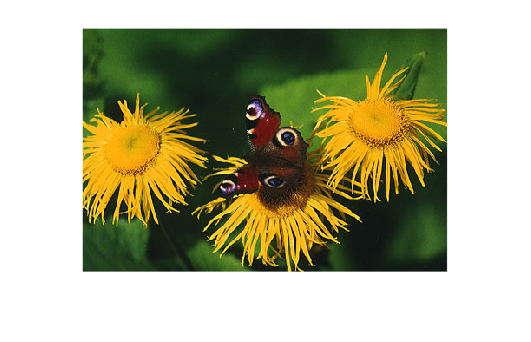

% 4.1

[R, G, B]=tiffread("Butterfly.tif");
imshowrgb(R ,G, B)

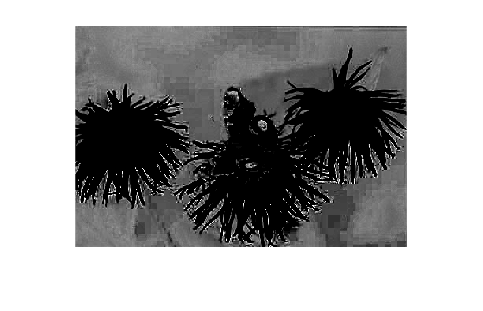


[C, M, Y, K]=rgb2cmyk(R,G,B);
figure(1)
imshow(C)

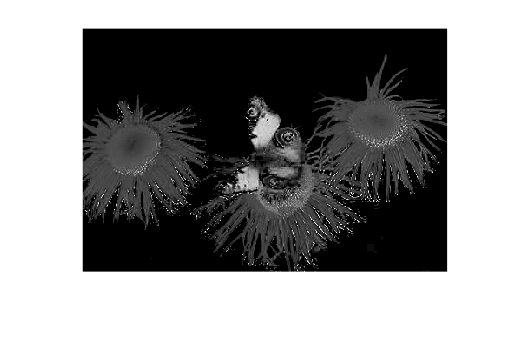

figure(2)
imshow(M)

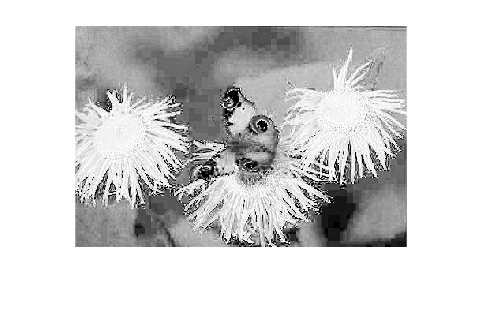

figure(3)
imshow(Y)

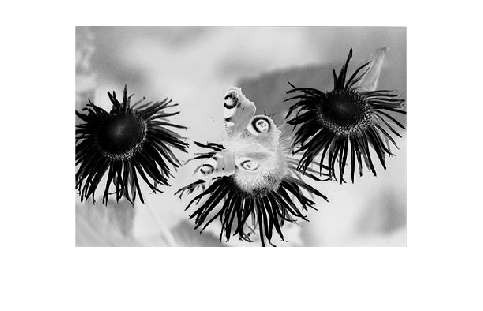

figure(4)
imshow(K)

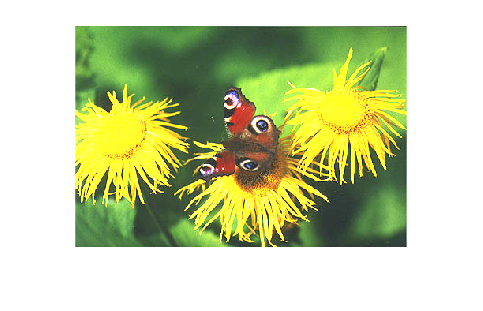

% 4.2
[L, a, b]=myrgb2lab(R,G,B);
[R2, G2, B2]=mylab2rgb(L+20, a, b);
imshowrgb(R2, G2, B2)

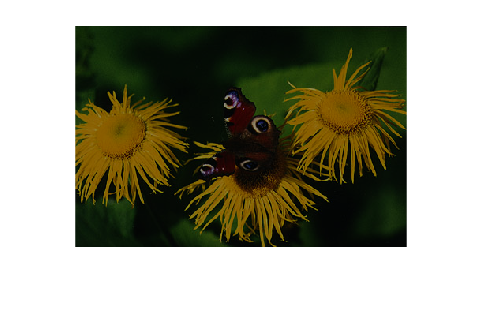

figure
[R3, G3, B3]=mylab2rgb(L-20, a, b);
imshowrgb(R3, G3, B3)

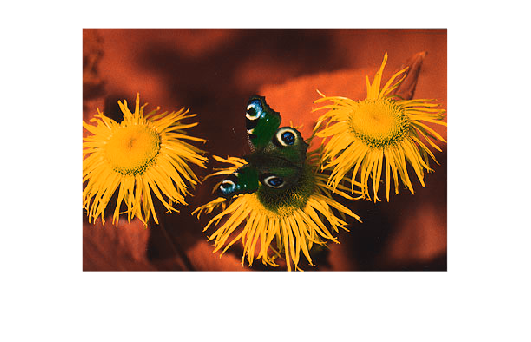


[R2, G2, B2]=mylab2rgb(L, -a, b);
imshowrgb(R2, G2, B2)

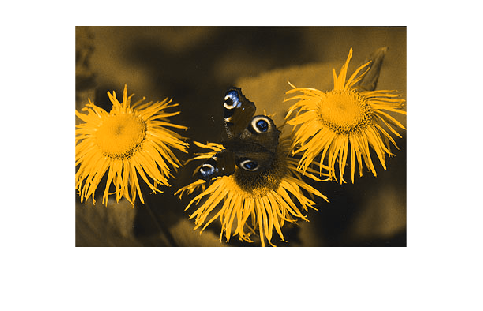

figure
[R2, G2, B2]=mylab2rgb(L, 0, b);
imshowrgb(R2, G2, B2)

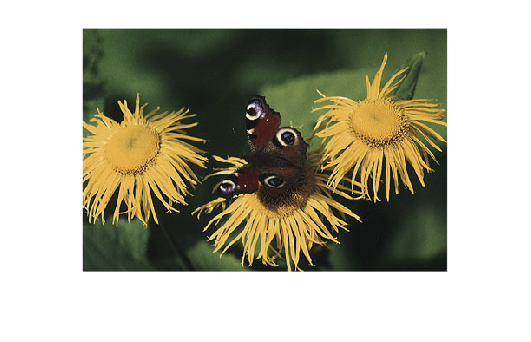

[R2, G2, B2]=mylab2rgb(L, 0.5*a, 0.5*b);
imshowrgb(R2, G2, B2)

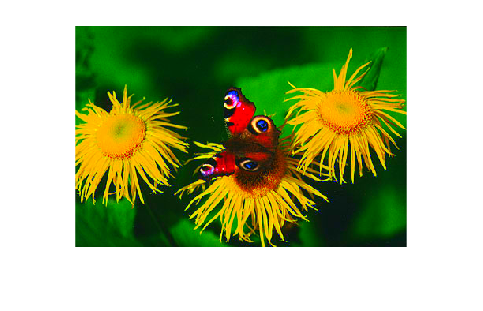

figure

[R2, G2, B2]=mylab2rgb(L, 3*a, 3*b);
imshowrgb(R2, G2, B2)

% 5.1

[X1, Y1, Z1] = spectra2xyz(1, CIED65);

[X2, Y2, Z2] = spectra2xyz(1, Tungsten60W);
[X3, Y3, Z3] = spectra2xyz(1, plank90K);

X3 = 97.0578

Y3 = 100

Z3 = 141.1759


[R1, G1, B1] = myxyz2rgb(X1, Y1, Z1);
[R2, G2, B2] = myxyz2rgb(X2, Y2, Z2);
[R3, G3, B3] = myxyz2rgb(X3, Y3, Z3);

help showRGB

  showRGB(RGB)
 
  RGB = Matris med RGB-värden som ska visas på skärmen.
  Matrisen bör se ut som följande:
  RGB=[r1 g1 b1;r2 g2 b2;...]




disp("break")

break


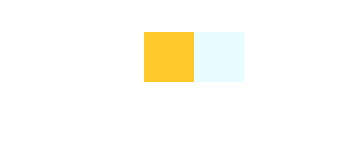

KUK = [R1 G1 B1; R2 G2 B2; R3 G3 B3];
showRGB(KUK);

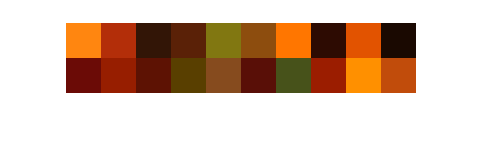

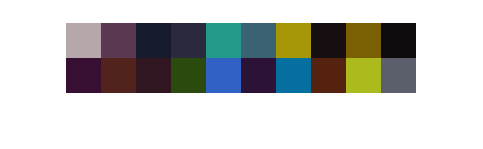

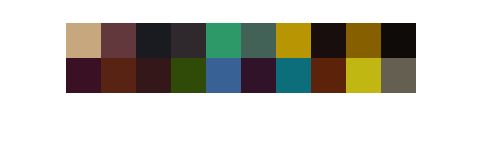

% 5.2
showRGB_20

ans =    42.6575   37.7851    9.2111


ans =    35.5059   37.1884   45.1131


ans =    35.1115   37.2965   34.8667


ans =    67.8620   67.4182   67.4989


ans =     0.1015   -1.7637   -1.0122


ans =     7.4954    6.9190    7.0603


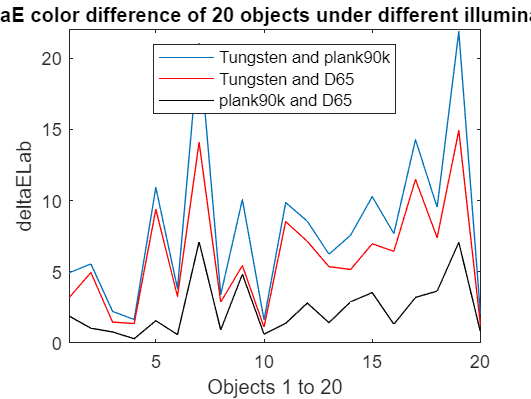

plot_deltaE

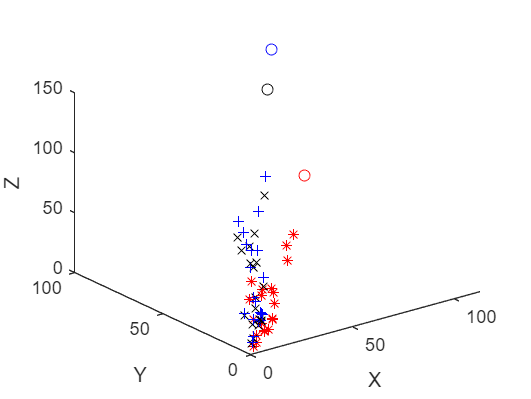

plot_XYZ

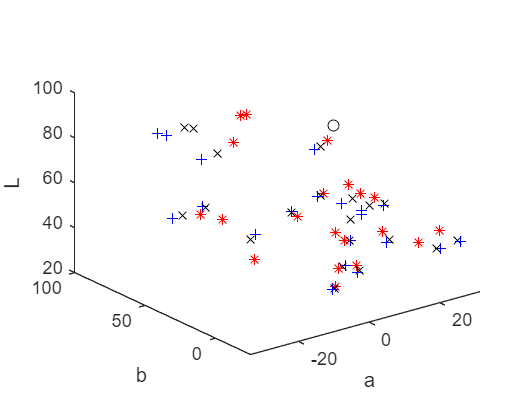

plot_Lab